# KNN Countries

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Load data from file. 

cities = readtable("./data/citydata.xlsx", Sheet='cities');
cities.Country = categorical(cities.Country);
cborders_1 = readmatrix("./data/citydata.xlsx", Sheet="cborders_1");
cborders_2 = readmatrix("./data/citydata.xlsx", Sheet="cborders_2");
cborders_3 = readmatrix("./data/citydata.xlsx", Sheet="cborders_3");
cborders_4 = readmatrix("./data/citydata.xlsx", Sheet="cborders_4");
cities

cities = 247×3 table
      Country      Latitude    Longitude
    ___________    ________    _________

    Netherlands      52.08        4.27  
    Belgium         50.833      4.3333  
    Netherlands      52.35      4.9166  
    France          48.867      2.3333  
    Belgium          51.05      3.7333  
    Belgium         50.985       5.052  
    Belgium         50.843      3.6045  
    Belgium          51.26      4.4028  
    Belgium         50.406      4.5279  
    Belgium         50.986      4.8365  
    Belgium         50.163      5.2662  
    Belgium         50.001      5.7153  
    Belgium         50.579      4.5345  
    Belgium          51.32      4.8559  
    Belgium         50.799      3.1218  
    Belgium         50.987      3.5236  


Fit a default KNN and visualize boundaries for later comparison.

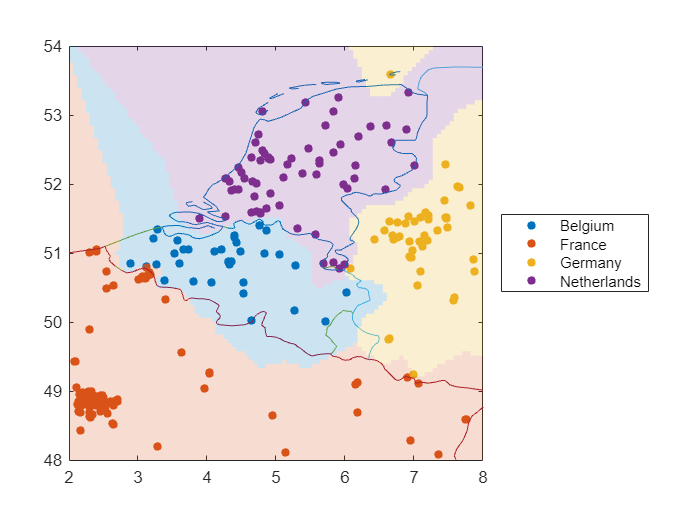

mdlKNN = fitcknn(cities, "Country");
plotBoundaries(mdlKNN, cities, cborders_1, cborders_2, cborders_3, cborders_4)

## Tasks 1-3

Look at the top right corner observation on the map, that is Borkum, an island in Germany. Since the number of neighbors is 1, the algorithm classified it correctly.

Cosine is usually used to calculate the similarity and direction between two vectors, thus it is not appropiate for our dataset. Such as with cosine, not all distance metrics will perform well in every dataset.

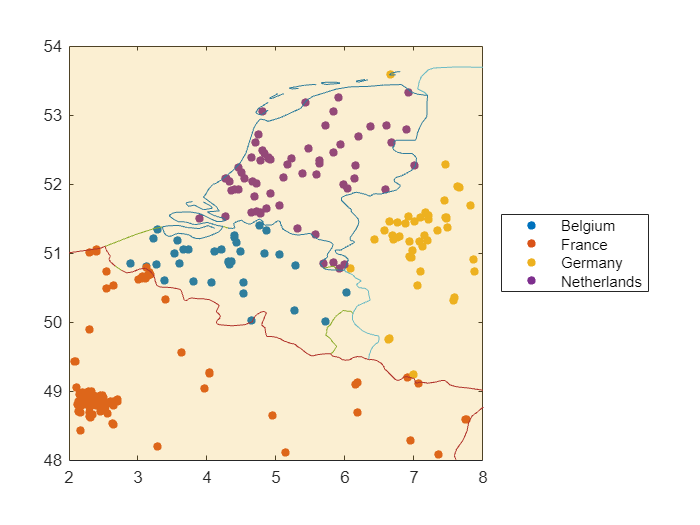

numNeighbors = 5;
mdl = fitcknn(cities, "Country", "NumNeighbors", numNeighbors, ...
                "Distance", "spearman", "DistanceWeight", "equal");
plotBoundaries(mdl, cities, cborders_1, cborders_2, cborders_3, cborders_4)

Do not edit. This function is used to plot the country boundaries along with the classification predictions given by the model.

function plotBoundaries(mdl, cities, cborders_1, cborders_2, cborders_3, cborders_4)
    % Make a grid of predictor points
    [x, y] = meshgrid(linspace(2, 8), linspace(48, 54));
    % Apply the model
    mdlpreds = predict(mdl, [y(:), x(:)]);
    % Visualize results
    gscatter(cities.Longitude, cities.Latitude, cities.Country, [], [], [], false);
    hold on
    plot(cborders_1(:, 1), cborders_1(:, 2))
    plot(cborders_2(:, 1), cborders_2(:, 2))
    plot(cborders_3(:, 1), cborders_3(:, 2))
    plot(cborders_4(:, 1), cborders_4(:, 2))
    pc = pcolor(x, y, reshape(mdlpreds, size(x)));
    pc.FaceAlpha = 0.2;
    pc.LineStyle = "none";
    c = colororder;
    colormap(c(1:length(unique(cities.Country)), :))
    grid off
    hold off
    axis equal
    axis([2 8 48 54])
    legend(categories(cities.Country), "Location", "eastoutside")
end